x_opt = optimize_closed_loop_poles(A, B, C);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           5    4.697129e+04     0.000e+00     1.000e+00     0.000e+00     1.555e+04  
    1          12    3.340038e+04     0.000e+00     4.900e-01     4.143e+01     2.690e+04  
    2          18    3.260672e+04     0.000e+00     7.000e-01     3.021e+01     1.490e+04  
    3          23    1.869613e+04     0.000e+00     1.000e+00     1.297e+01     1.030e+04  
    4          28    1.506777e+04     0.000e+00     1.000e+00     3.703e-01     1.070e+04  
    5          39   -3.277343e+01     0.000e+00     1.176e-01     2.263e-01     1.057e+03  
    6          53   -3.298001e+01     0.000e+00     4.035e-02     8.020e-02     1.015e+03  
    7          76   -3.303896e+01     0.000e+00     1.628e-03     2.030e-02     1.014e+03  
    8         106   -3.305904e+01     0.000e+00     1.341e-04     6.706e-03     1.

% Construct poles from result
p1 = x_opt(1) + 1j*x_opt(2);
p2 = x_opt(1) - 1j*x_opt(2);
p3 = x_opt(3);
p4 = x_opt(4);
desired_poles = [p1, p2, p3, p4];

K = place(A, B, desired_poles)

K = 1.0e+05 *

    0.0013    0.0478    0.0380    1.0334



F = pinv(C * (-inv(A - B*K) * B))  % Base gain

F = 5.4768e+03


% Closed-loop System and Loop Gain
Acl = A - B*K;
sys_cl = ss(Acl, B*F, C, 0);            % Tracking TF: θ/θ_ref
sys_u2r = inv(1 + ss(A,B,K,0)) * F;     % Input/Ref: u/θ_ref
Loop_gain_neg = tf(ss(A, B, K, 0));                % Negative Loop Gain

open_loop_poles = pole(ss(A,B,C,D));
closed_loop_poles = pole(sys_cl)

closed_loop_poles =  -80.0000 + 0.0000i
 -60.0000 + 0.0000i
  -0.1172 + 4.6384i
  -0.1172 - 4.6384i



% --------- Margins and Bandwidth ---------
[GM, PM] = margin(Loop_gain_neg);
GM_dB = 20*log10(GM);
bw = bandwidth(sys_cl, -3.05);

fprintf('--- System Stability and Performance ---\n');

--- System Stability and Performance ---


fprintf('Gain Margin: %.2f dB\n', GM_dB);

Gain Margin: Inf dB


fprintf('Phase Margin: %.2f deg\n', PM);

Phase Margin: 77.90 deg


fprintf('Closed-Loop Bandwidth: %.2f rad/s (%.2f Hz)\n', bw, bw/(2*pi));

Closed-Loop Bandwidth: 45.56 rad/s (7.25 Hz)


fprintf('Closed-loop Poles:\n');

Closed-loop Poles:


disp(closed_loop_poles);

 -80.0000 + 0.0000i
 -60.0000 + 0.0000i
  -0.1172 + 4.6384i
  -0.1172 - 4.6384i



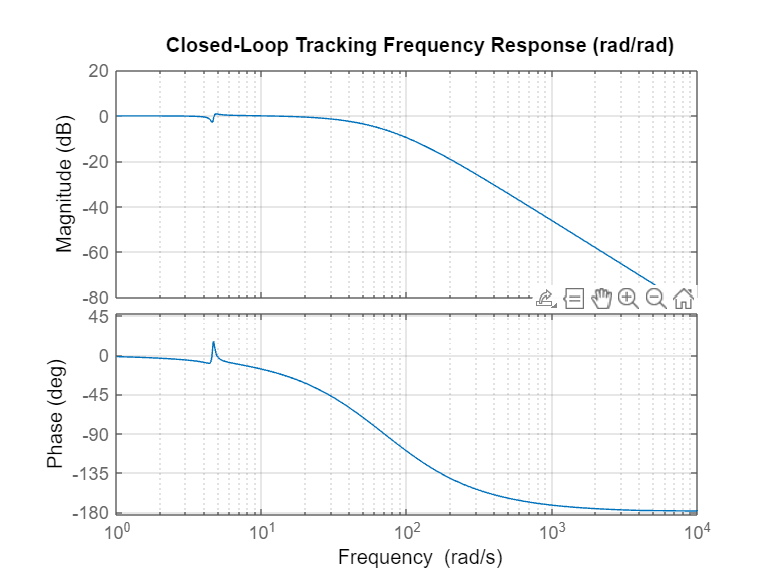


% Closed-loop tracking response (rad/rad)
figure;
bode(sys_cl); grid on;
title('Closed-Loop Tracking Frequency Response (rad/rad)');

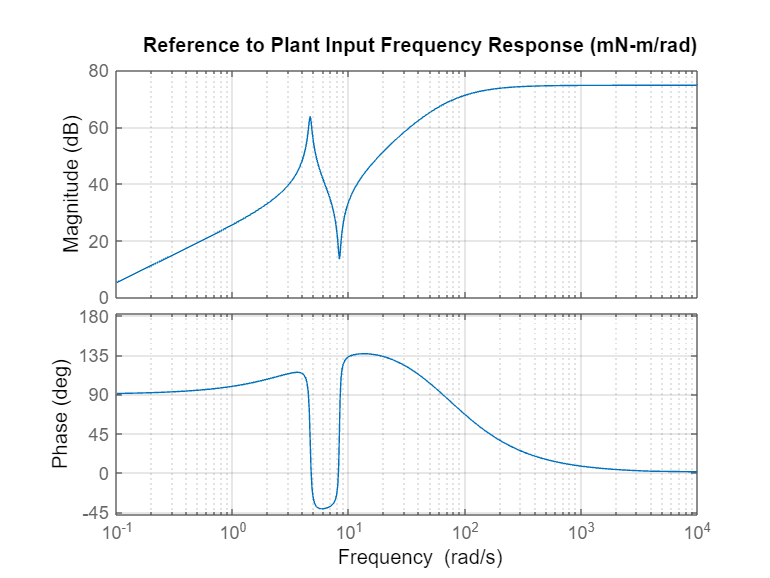


% From reference to plant input (mN-m/rad)
figure;
bode(sys_u2r); grid on;
title('Reference to Plant Input Frequency Response (mN-m/rad)');

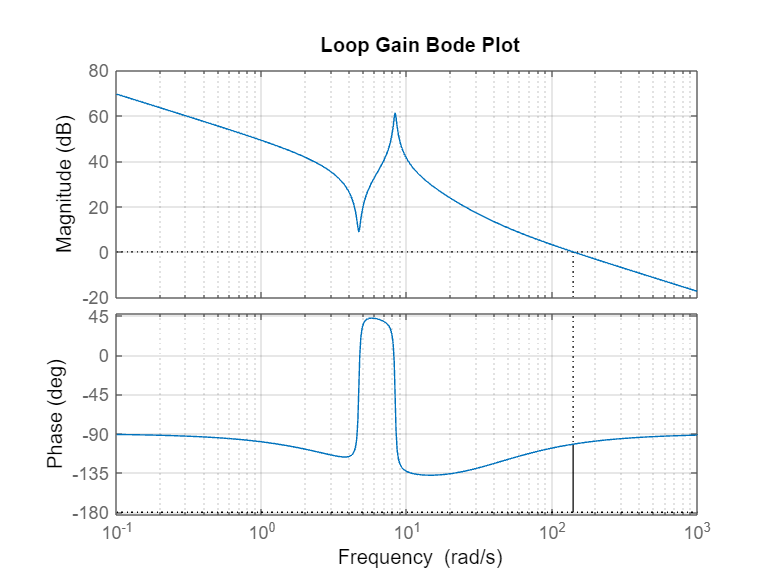


% Loop gain
figure;
margin(Loop_gain_neg); grid on;
title('Loop Gain Bode Plot');

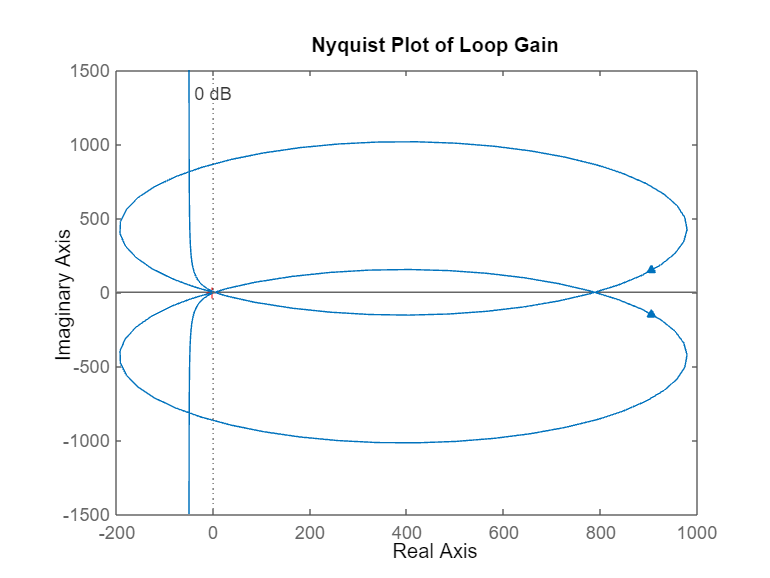


figure;
nyquist(Loop_gain_neg);
title('Nyquist Plot of Loop Gain');
grid on;

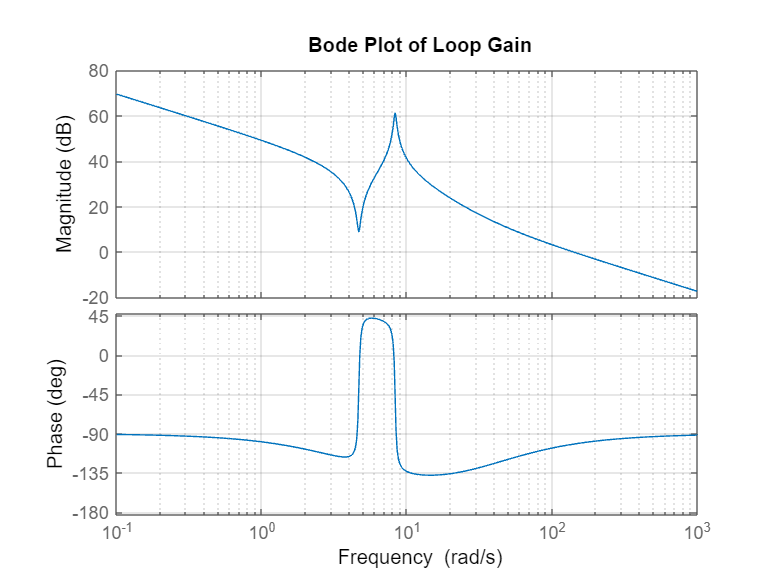


figure;
bode(Loop_gain_neg);
title('Bode Plot of Loop Gain');
grid on;

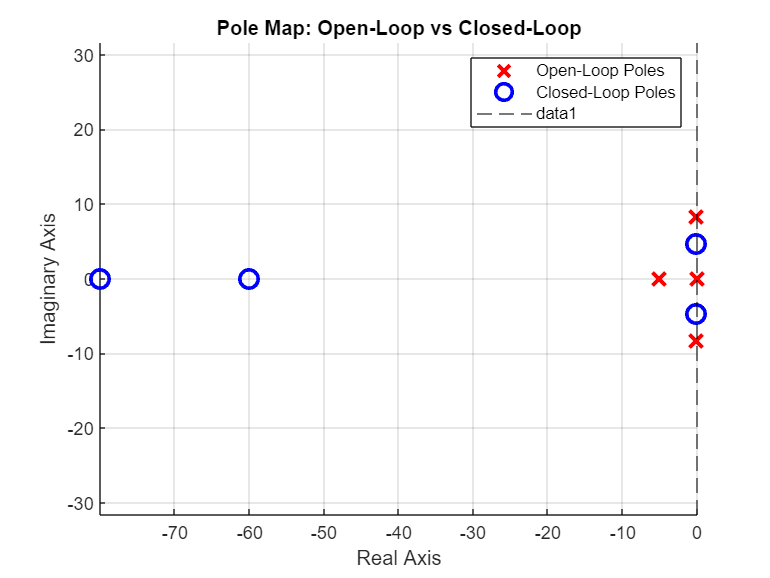


% --------- Pole Plot ---------
figure; hold on; grid on; axis equal;
plot(real(open_loop_poles), imag(open_loop_poles), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(closed_loop_poles), imag(closed_loop_poles), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
legend('Open-Loop Poles', 'Closed-Loop Poles');
xlabel('Real Axis'); ylabel('Imaginary Axis');
title('Pole Map: Open-Loop vs Closed-Loop');
xline(0, '--k');

function x_opt = optimize_closed_loop_poles(A, B, C)
    % Initial guess
    x0 = [-0.5, 5.5, -10, -12];

    % Bounds: Ensure LHP and realistic pole locations
    lb = [-50, 0.5, -60, -80];
    ub = [-0.01, 30, -0.05, -0.05];

    options = optimoptions('fmincon', ...
        'Display', 'iter', ...
        'Algorithm', 'sqp', ...
        'MaxFunctionEvaluations', 1000);

    cost = @(x) bandwidth_cost_soft_penalty(x, A, B, C);

    % fmincon call
    x_opt = fmincon(cost, x0, [], [], [], [], lb, ub, [], options);
end

function cost = bandwidth_cost_soft_penalty(x, A, B, C)
    a_real = x(1);
    a_imag = x(2);
    p3 = x(3);
    p4 = x(4);

    desired_poles = [a_real + 1j*a_imag, a_real - 1j*a_imag, p3, p4];

    try
        % Ensure poles are not too close
        min_sep = min(abs(diff(sort(real(desired_poles)))));
        closeness_penalty = 0;
        if min_sep < 0.05
            closeness_penalty = 5000 * (0.05 - min_sep)^2;
        end

        % Pole placement
        K = place(A, B, desired_poles);
        Acl = A - B*K;

        % Tracking gain
        F = pinv(C * (-Acl \ B));

        % Closed-loop TF
        sys_cl = ss(Acl, B*F, C, 0);

        % Actual bandwidth
        bw = bandwidth(sys_cl, -3.05);

        % Soft penalty if bandwidth < 6.28 rad/s (1 Hz)
        penalty = 5000 * max(0, 6.28 - bw)^2;

        % Final cost (we minimize negative bandwidth + penalties)
        cost = -bw + penalty + closeness_penalty;

    catch
        cost = 1e6;  % unplaceable or unstable
    end
end